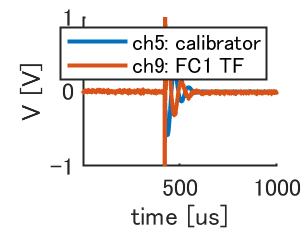

%%%230118のデータを用いたcalibration
%較正器は10kA/V

folder_directory_rogo = getenv('rogo_path');
date=230118;

aquisition_rate=10; %[MHz]
offset=0;
t_start = 1; % us
t_end = 1000; % us
t_start=t_start-offset;t_end=t_end-offset; % set offset
time_step = 1;%0.2; % us; time step of plot; must be an integer times of time step of raw data; larger time step gives faster plotting.
step = aquisition_rate * time_step;
x = t_start * aquisition_rate : step : t_end * aquisition_rate;

upper = 1;%0.6; % upper limit of y axis
lower = -1;%-0.4; % lower limit of y axis

%shot1,ch5:calibrator,ch9:FC1 TF
shot=1;
[date_str,shot_str,path] = directory_generation_Rogowski(date,shot,folder_directory_rogo);
data1 = readmatrix(path);
data1(:,2:end)=data1(:,2:end)-mean(data1(1:3000,2:end));
channels1=[5,9];
figure
hold on
for i = channels1
    plot(x/aquisition_rate+offset,data1(x,i+2),'LineWidth',2);
end
legend('ch5: calibrator','ch9: FC1 TF')
ylim([lower upper]);
xlim([t_start+offset t_end+offset]);
xlabel('time [us]','FontSize',12);
ylabel('V [V]','FontSize',12);
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1; 
hold off


t_calib = 450:500;
t_calib = t_calib(1) * aquisition_rate : step : t_calib(end) * aquisition_rate;
a = data1(t_calib,7);
b = data1(t_calib,11);
b = b(b~=0);
a = a(b~=0);
calibration_9=-10.*mean(a./b)

calibration_9 = 8.8940

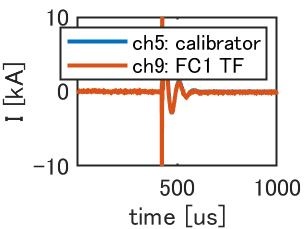


figure
plot(x/aquisition_rate+offset,-10.*data1(x,7),'LineWidth',2);
hold on
plot(x/aquisition_rate+offset,calibration_9.*data1(x,11),'LineWidth',2);
hold off
legend('ch5: calibrator','ch9: FC1 TF')
ylim([-10 10]);
xlim([t_start+offset t_end+offset]);
xlabel('time [us]','FontSize',12);
ylabel('I [kA]','FontSize',12);
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1; 

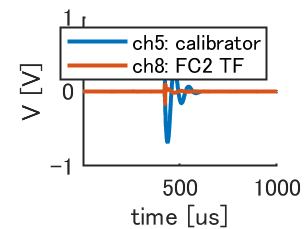


%shot2,ch5:calibrator,ch8:FC2 TF
shot=2;
[date_str,shot_str,path] = directory_generation_Rogowski(date,shot,folder_directory_rogo);
data2 = readmatrix(path);
data2(:,2:end)=data2(:,2:end)-data2(offset+1,2:end);
channels1=[5,8];
figure
hold on
for i = channels1
    plot(x/aquisition_rate+offset,data2(x,i+2),'LineWidth',2);
end
legend('ch5: calibrator','ch8: FC2 TF')
ylim([lower upper]);
xlim([t_start+offset t_end+offset]);
xlabel('time [us]','FontSize',12);
ylabel('V [V]','FontSize',12);
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1; 
hold off


t_calib = 450:500;
t_calib = t_calib(1) * aquisition_rate : step : t_calib(end) * aquisition_rate;
a = data2(t_calib,7);
b = data2(t_calib,10);
b = b(b~=0);
a = a(b~=0);
calibration_8=-10.*mean(a./b)

calibration_8 = 202.1929

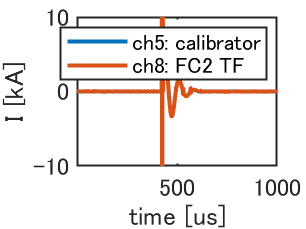


figure
plot(x/aquisition_rate+offset,-10.*data2(x,7),'LineWidth',2);
hold on
plot(x/aquisition_rate+offset,calibration_8.*data2(x,10),'LineWidth',2);
hold off
legend('ch5: calibrator','ch8: FC2 TF')
ylim([-10 10]);
xlim([t_start+offset t_end+offset]);
xlabel('time [us]','FontSize',12);
ylabel('I [kA]','FontSize',12);
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1; 

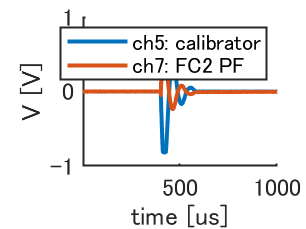


%shot3,ch5:calibrator,ch7:FC2 PF(積分器変更)
shot=3;
[date_str,shot_str,path] = directory_generation_Rogowski(date,shot,folder_directory_rogo);
data3 = readmatrix(path);
data3(:,2:end)=data3(:,2:end)-data3(offset+1,2:end);
channels1=[5,7];
figure
hold on
for i = channels1
    plot(x/aquisition_rate+offset,data3(x,i+2),'LineWidth',2);
end
legend('ch5: calibrator','ch7: FC2 PF')
ylim([lower upper]);
xlim([t_start+offset t_end+offset]);
xlabel('time [us]','FontSize',12);
ylabel('V [V]','FontSize',12);
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1; 
hold off


t_calib = 440:500;
t_calib = t_calib(1) * aquisition_rate : step : t_calib(end) * aquisition_rate;
a = data3(t_calib,7);
b = data3(t_calib,9);
b = b(b~=0);
a = a(b~=0);
calibration_7=-10.*mean(a./b)

calibration_7 = 18.1794

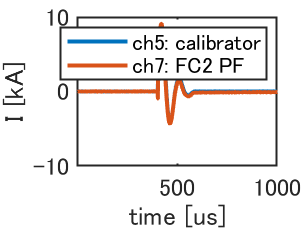


figure
plot(x/aquisition_rate+offset,-10.*data3(x,7),'LineWidth',2);
hold on
plot(x/aquisition_rate+offset,calibration_7.*data3(x,9),'LineWidth',2);
hold off
legend('ch5: calibrator','ch7: FC2 PF')
ylim([-10 10]);
xlim([t_start+offset t_end+offset]);
xlabel('time [us]','FontSize',12);
ylabel('I [kA]','FontSize',12);
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1; 

function [date_str,shot_str,data_dir] = directory_generation_Rogowski(date,shot,folder_directory_rogo)
    date_str = num2str(date);
    if shot < 10
        data_dir = [folder_directory_rogo,date_str,'\',date_str,'00',num2str(shot),'.txt'];
        shot_str = ['00',num2str(shot)];
    elseif shot < 100
        data_dir = [folder_directory_rogo,date_str,'\',date_str,'0',num2str(shot),'.txt'];
        shot_str = ['0',num2str(shot)];
    elseif shot < 1000
        data_dir = [folder_directory_rogo,date_str,'\',date_str,num2str(shot),'.txt'];
        shot_str = num2str(shot);
    else
        disp('More than 999 shots! You need some rest!!!');
        return
    end
end